# Hoja 1B

Ejercicio 9

%% Ejercicio 9: Ecuación cuadrática
fprintf('=== EJERCICIO 9: RAÍCES CUADRÁTICAS ===\n');

=== EJERCICIO 9: RAÍCES CUADRÁTICAS ===



a = 1;
b = -100.0001;
c = 0.01;

% Cálculo con fórmula clásica
discriminante = b^2 - 4*a*c;
x1_clasica = (-b + sqrt(discriminante))/(2*a);
x2_clasica = (-b - sqrt(discriminante))/(2*a);

% Cálculo con fórmula mejorada para raíz pequeña
x1_mejor = (-b + sqrt(discriminante))/(2*a);
x2_mejor = (2*c)/(-b - sqrt(discriminante));

fprintf('Fórmula clásica (15 decimales):\n');

Fórmula clásica (15 decimales):


fprintf('x1 = %.15f\n', x1_clasica);

x1 = 100.000000000000000


fprintf('x2 = %.15f\n\n', x2_clasica);

x2 = 0.000100000000003




fprintf('Fórmula mejorada para raíz pequeña:\n');

Fórmula mejorada para raíz pequeña:


fprintf('x1 = %.15f\n', x1_mejor);

x1 = 100.000000000000000


fprintf('x2 = %.15f\n\n', x2_mejor);

x2 = 99.999999996680344




% Verificación
fprintf('Comprobación sustituyendo en ecuación:\n');

Comprobación sustituyendo en ecuación:


error1 = a*x1_clasica^2 + b*x1_clasica + c;
error2 = a*x2_clasica^2 + b*x2_clasica + c;
fprintf('Error con x1 clásica: %.15f\n', error1);

Error con x1 clásica: -0.000000000000218


fprintf('Error con x2 clásica: %.15f\n', error2);

Error con x2 clásica: -0.000000000000332



error1m = a*x1_mejor^2 + b*x1_mejor + c;
error2m = a*x2_mejor^2 + b*x2_mejor + c;
fprintf('Error con x1 mejorada: %.15f\n', error1m);

Error con x1 mejorada: -0.000000000000218


fprintf('Error con x2 mejorada: %.15f\n', error2m);

Error con x2 mejorada: -0.000000331965784


Ejercicio 10

%% Ejercicio 10: Cociente incremental para cos(1)
fprintf('\n=== EJERCICIO 10: APROXIMACIÓN DE cos(1) ===\n');


=== EJERCICIO 10: APROXIMACIÓN DE cos(1) ===



valor_exacto = 0.54030230586814;
h_values = 10.^(-(1:16));  % h de 10^-1 a 10^-16

fprintf('%-10s %-25s %-25s %-25s\n', 'h', 'Aproximación', 'Error absoluto', 'Error relativo');

h          Aproximación              Error absoluto            Error relativo           


fprintf('%s\n', repmat('-', 90, 1));

------------------------------------------------------------------------------------------



for i = 1:length(h_values)
    h = h_values(i);
    aproximacion = (sin(1 + h) - sin(1)) / h;
    error_abs = abs(aproximacion - valor_exacto);
    error_rel = error_abs / valor_exacto;
    
    fprintf('%-10.0e %-25.15f %-25.15f %-25.15f\n', ...
            h, aproximacion, error_abs, error_rel);
end

1e-01      0.497363752535389         0.042938553332751         0.079471349402736        
1e-02      0.536085981011869         0.004216324856271         0.007803640314835        
1e-03      0.539881480360327         0.000420825507813         0.000778870464262        
1e-04      0.540260231418621         0.000042074449519         0.000077872052482        
1e-05      0.540298098505865         0.000004207362275         0.000007787052229        
1e-06      0.540301885121330         0.000000420746810         0.000000778724808        
1e-07      0.540302264040449         0.000000041827691         0.000000077415349        
1e-08      0.540302302898255         0.000000002969885         0.000000005496711        
1e-09      0.540302358409406         0.000000052541266         0.000000097244201        
1e-10      0.540302247387103         0.000000058481037         0.000000108237622        
1e-11      0.540301137164079         0.000001168704061         0.000002163055846        
1e-12      0.54034554


% Gráfica del error vs h
figure;
loglog(h_values, abs((sin(1+h_values)-sin(1))./h_values - valor_exacto), 'b-o', 'LineWidth', 1.5);
hold on;
grid on;
xlabel('h (log scale)');
ylabel('Error absoluto (log scale)');
title('Error en aproximación de cos(1) vs tamaño de paso h');
legend('Error absoluto', 'Location', 'best');

Ejercicio 11

%% Ejercicio 11: Potencias del número áureo
fprintf('\n=== EJERCICIO 11: POTENCIAS DEL NÚMERO ÁUREO ===\n');


=== EJERCICIO 11: POTENCIAS DEL NÚMERO ÁUREO ===



phi = (sqrt(5) - 1)/2;  % φ = (√5 - 1)/2
n = 100;

% Algoritmo 1: Diferencias
phi_diff = zeros(1, n+1);
phi_diff(1) = 1;        % φ^0
phi_diff(2) = phi;      % φ^1
for k = 3:n+1
    phi_diff(k) = phi_diff(k-2) - phi_diff(k-1);
end

% Algoritmo 2: Productos
phi_prod = zeros(1, n+1);
phi_prod(1) = 1;        % φ^0
phi_prod(2) = phi;      % φ^1
for k = 3:n+1
    phi_prod(k) = phi * phi_prod(k-1);
end

% Valores exactos (para comparación)
phi_exact = phi.^(0:n);

% Cálculo de errores relativos
error_rel_diff = abs((phi_diff - phi_exact) ./ phi_exact);
error_rel_prod = abs((phi_prod - phi_exact) ./ phi_exact);

% Mostrar algunos valores
fprintf('\nPrimeros 10 valores:\n');


Primeros 10 valores:


fprintf('%-5s %-20s %-20s %-20s %-20s %-20s\n', ...
        'n', 'Diferencias', 'Productos', 'Exacto', 'Error Diff', 'Error Prod');

n     Diferencias          Productos            Exacto               Error Diff           Error Prod          


for k = 1:11
    fprintf('%-5d %-20.15f %-20.15f %-20.15f %-20.2e %-20.2e\n', ...
            k-1, phi_diff(k), phi_prod(k), phi_exact(k), ...
            error_rel_diff(k), error_rel_prod(k));
end

0     1.000000000000000    1.000000000000000    1.000000000000000    0.00e+00             0.00e+00            
1     0.618033988749895    0.618033988749895    0.618033988749895    0.00e+00             0.00e+00            
2     0.381966011250105    0.381966011250105    0.381966011250105    2.91e-16             0.00e+00            
3     0.236067977499790    0.236067977499790    0.236067977499790    2.35e-16             0.00e+00            
4     0.145898033750315    0.145898033750316    0.145898033750316    1.52e-15             0.00e+00            
5     0.090169943749475    0.090169943749474    0.090169943749474    2.62e-15             1.54e-16            
6     0.055728090000841    0.055728090000841    0.055728090000841    8.34e-15             1.25e-16            
7     0.034441853748634    0.034441853748633    0.034441853748633    1.99e-14             2.01e-16            
8     0.021286236252207    0.021286236252208    0.021286236252208    5.43e-14             1.63e-16            
9

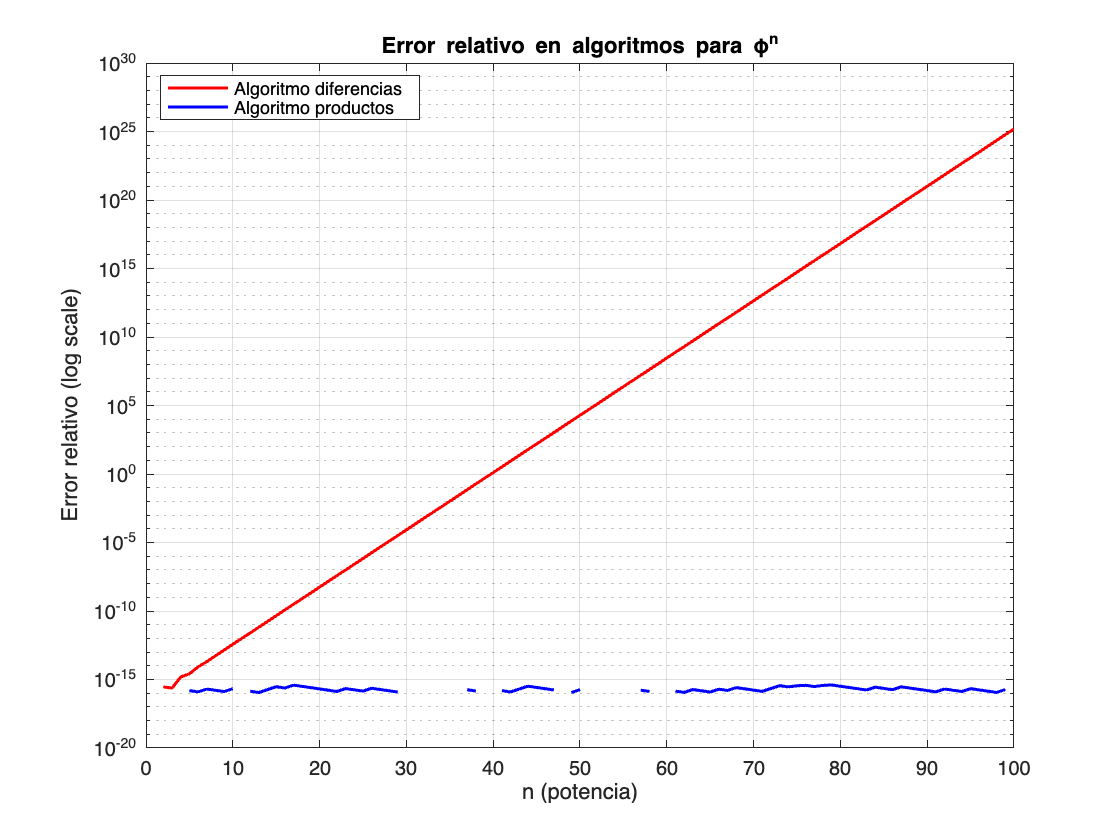


% Gráfica de errores
figure;
semilogy(0:n, error_rel_diff, 'r-', 'LineWidth', 1.5);
hold on;
semilogy(0:n, error_rel_prod, 'b-', 'LineWidth', 1.5);
grid on;
xlabel('n (potencia)');
ylabel('Error relativo (log scale)');
title('Error relativo en algoritmos para φ^n');
legend('Algoritmo diferencias', 'Algoritmo productos', 'Location', 'best');
xlim([0, 100]);

Ejercicio 12

%% Ejercicio 12: Comparación de algoritmos Fibonacci
fprintf('\n=== EJERCICIO 12: ALGORITMOS FIBONACCI ===\n');


=== EJERCICIO 12: ALGORITMOS FIBONACCI ===



% Implementación recursiva (ineficiente)
tic;
n = 30;  % No usar n grande por eficiencia
fib_rec = rfibonacci(n);
time_rec = toc;

% Implementación iterativa
tic;
fib_iter = ifibonacci(n);
time_iter = toc;

fprintf('Fibonacci(%d):\n', n);

Fibonacci(30):


fprintf('  Recursivo: %d (tiempo: %.4f s)\n', fib_rec, time_rec);

  Recursivo: 832040 (tiempo: 0.0956 s)


fprintf('  Iterativo: %d (tiempo: %.6f s)\n', fib_iter, time_iter);

  Iterativo: 832040 (tiempo: 0.011268 s)



% Comparación de tiempos para diferentes n
n_values = [10, 20, 30, 35];
fprintf('\nComparación de tiempos:\n');


Comparación de tiempos:


fprintf('%-10s %-15s %-15s\n', 'n', 'Tiempo Rec', 'Tiempo Iter');

n          Tiempo Rec      Tiempo Iter    


for n_test = n_values
    if n_test <= 35  % Cuidado con recursivo para n grande
        tic;
        rfibonacci(n_test);
        t_rec = toc;
    else
        t_rec = Inf;
    end
    
    tic;
    ifibonacci(n_test);
    t_iter = toc;
    
    fprintf('%-10d %-15.4f %-15.6f\n', n_test, t_rec, t_iter);
end

10         0.0003          0.001003       
20         0.0003          0.000330       
30         0.0375          0.000395       
35         0.4217          0.000893       



% Funciones auxiliares
function f = rfibonacci(n)
    if n == 1 || n == 2
        f = 1;
    else
        f = rfibonacci(n-1) + rfibonacci(n-2);
    end
end

function f = ifibonacci(n)
    if n == 1 || n == 2
        f = 1;
    else
        a = zeros(1, n);
        a(1) = 1;
        a(2) = 1;
        for i = 3:n
            a(i) = a(i-1) + a(i-2);
        end
        f = a(n);
    end
end